# Some interesting scripts that could be used to test forward kinematics.

## Set up the data classes

close
clear
clc
obj = UpperLimbModelToolbox();

ans =
     []
ans =
     []


## Set the initial configuration

q_init = [1 ; 0.2; 0; 1; 1; 0.2; 1]

q_init =     1.0000
    0.2000
         0
    1.0000
    1.0000
    0.2000
    1.0000


T = obj.forwardKinematics(q_init);
x = zeros(6,1);
x(1:3) = T(1:3,4);
x(4:6) = rotm2eul(T(1:3,1:3), 'XYZ');

x_shift = [-0.05; 0.02; 0.03];
R_move = [0.4; 0.3; 0.2];

x_d = x + [x_shift; R_move];
T_d = eye(4);
T_d(1:3,4) = x_d(1:3);
T_d(1:3,1:3) = eul2rotm(x_d(4:6)', 'XYZ');

T_d

T_d =     0.1941   -0.1085    0.9750    0.2534
    0.8741    0.4702   -0.1217   -0.4540
   -0.4453    0.8758    0.1861    0.2033
         0         0         0    1.0000


T

T =     0.4767   -0.1525    0.8657    0.3034
    0.4468    0.8902   -0.0892   -0.4740
   -0.7571    0.4293    0.4925    0.1733
         0         0         0    1.0000


## Inverse kinematic solver: CLIK_toolbox

% solve the inverse kinematics
tic
[q, isValid, info] = obj.inverseKinematics(T_d, q_init, "methods", "toolbox_CLIK")

ik_numeric: ik finished!


q =     0.7506
    0.2022
   -0.2941
    0.8850
    0.6392
   -0.4580
    1.7587


isValid = logical
   0

info = 包含以下字段的 struct :
        status: 1
         x_res: [6×1 double]
         phi_x: [6×1 double]
          iter: 70
    retry_iter: 0

toc

历时 2.016215 秒。


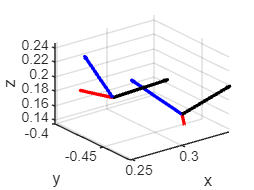


% plot the result
figure();
T_fin = obj.forwardKinematics(q);
obj.model.plot_frame(T_d(1:3,4), T_d(1:3,1:3), 0.05);
obj.model.plot_frame(T(1:3,4), T(1:3,1:3), 0.05);
obj.model.plot_frame(T_fin(1:3,4), T_fin(1:3,1:3), 0.03);

## Inverse kinematic solver: LM_toolbox

% solve the inverse kinematics
tic
[q, isValid, info] = obj.inverseKinematics(T_d, q_init, "methods", "toolbox_LM")

IK_numeric_LM: ik finished!


q =     0.7047
    0.2059
   -0.2736
    0.8835
    0.6184
   -0.4530
    1.7443


isValid = logical
   0

info = 包含以下字段的 struct :
        status: 1
         x_res: [6×1 double]
         phi_x: [6×1 double]
          iter: 6
    retry_iter: 0

toc

历时 0.186158 秒。


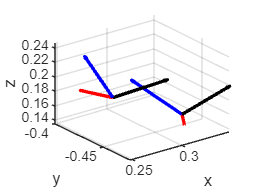


% plot the result
figure();
T_fin = obj.forwardKinematics(q);
obj.model.plot_frame(T_d(1:3,4), T_d(1:3,1:3), 0.05);
obj.model.plot_frame(T(1:3,4), T(1:3,1:3), 0.05);
obj.model.plot_frame(T_fin(1:3,4), T_fin(1:3,1:3), 0.03);